## Case15_1

Loading case15_1

load('15_1.mat'); 

Input values

y1_15_1=scope.signals(1).values; 

y1_15_1=y1_15_1.';
x1_15_1=tout;
x1_15_1=x1_15_1.';

figure
plot(x1_15_1,y1_15_1);
hold on

Response values

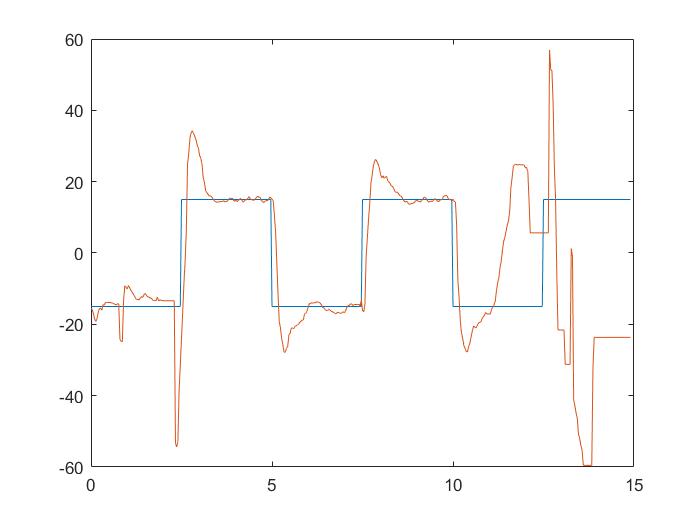

y2_15_1=scope.signals(2).values; 

y3_15_1=squeeze(y2_15_1);
y3_15_1=y3_15_1.';
constref=80;
y3_15_1=y3_15_1-constref;

plot(x1_15_1,y3_15_1);
hold off

Chosing points(step 4)

case15_1_y=y3_15_1(225:300); 

Forcing first point as y=0

const15_1=y3_15_1(225);
case15_1_y=case15_1_y-const15_1;
case15_1_t=x1_15_1(1:76);

figure
plot(case15_1_t,case15_1_y);
hold on

Picking points from the reference for comparison

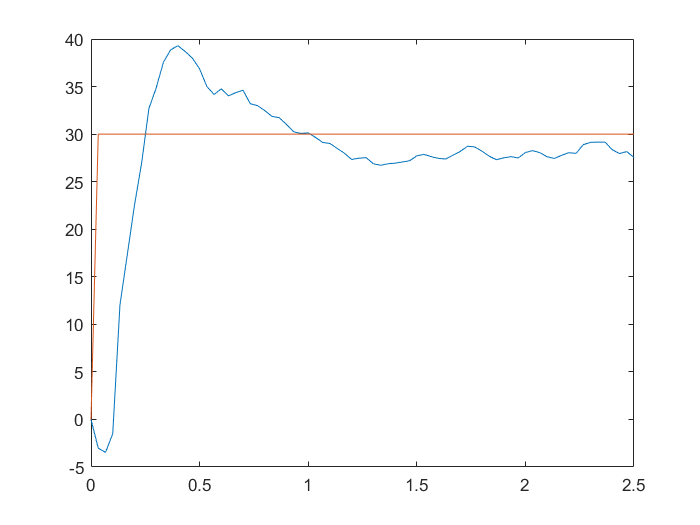

case15_1_yref=y1_15_1(225:300);
const15_1_yref=y1_15_1(225);
case15_1_yref=case15_1_yref-const15_1_yref;


plot(case15_1_t,case15_1_yref);
hold off

Tratamento de dados para Deconv

case15_1_yref_deconv=y1_15_1(226:254); %U(0)->U(N-1)
const15_1_yref_deconv=y1_15_1(226);
U=case15_1_yref_deconv+const15_1_yref_deconv;
Udeconv_15_1=U';

case15_1_y_deconv=y3_15_1(227:255); %Y(1)->Y(N)(um step a tráz de U)
const15_1_deconv=y3_15_1(226);
Y=case15_1_y_deconv-const15_1_deconv;
Ydeconv_15_1=Y';
Ydeconv_15_1(1)=0;

% Ydeconv_15_1(29)=0;
% Ydeconv_30_1_2 = circshift(Ydeconv_15_1,1);
% Ydeconv_30_1_2(2)=-1;

Ts=1/30;

Performing Deconvolution 

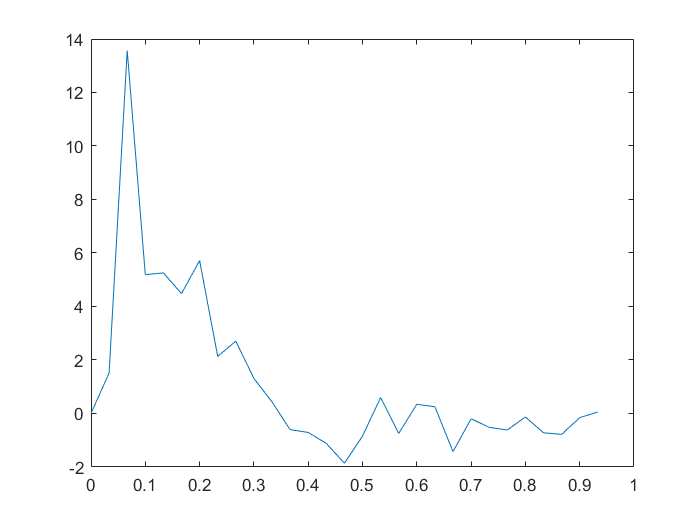

g_15_1 = Deconv(Udeconv_15_1,Ydeconv_15_1,Ts);

T_15_1=x1_15_1(1:29);
 
figure
% plot(T_30_1,Ydeconv_30_1_2);
% hold on

plot(T_15_1,g_15_1);
hold off

## Case20_1

Loading case20_1

load('20_1.mat');

Input values

y1_20_1=scope.signals(1).values; 

y1_20_1=y1_20_1.';
x1_20_1=tout;
x1_20_1=x1_20_1.';

figure
plot(x1_20_1,y1_20_1);
hold on

Response values

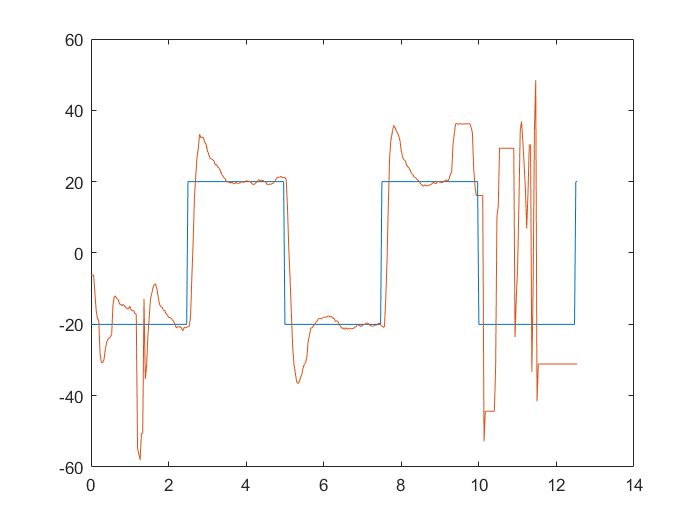

y2_20_1=scope.signals(2).values; 

y3_20_1=squeeze(y2_20_1);
y3_20_1=y3_20_1.';
constref=80;
y3_20_1=y3_20_1-constref;

plot(x1_20_1,y3_20_1);
hold off

Chosing points (step 3)

case20_1_y=y3_20_1(150:225); 

Forcing first point as y=0

const20_1=y3_20_1(150);
case20_1_y=case20_1_y-const20_1; 
case20_1_t=x1_20_1(1:76);
case20_1_y=case20_1_y*(-1); %%flipping negative to positive

figure
plot(case20_1_t,case20_1_y);
hold on

Picking points from the reference for comparison

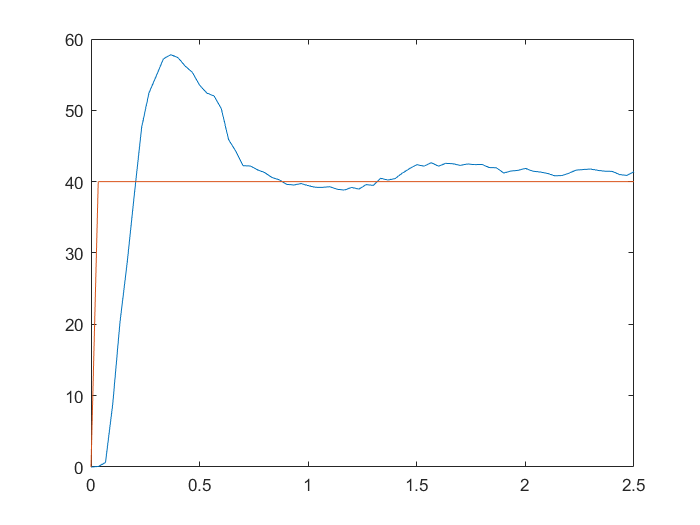

case20_1_yref=y1_20_1(150:225);
const20_1_yref=y1_20_1(150);
case20_1_yref=case20_1_yref-const20_1_yref;
case20_1_yref=case20_1_yref*(-1); %%flipping negative to positive

plot(case20_1_t,case20_1_yref);
hold off

## Case25_1

Loading case25_1

load('25_1.mat');

Input Values

y1_25_1=scope.signals(1).values; 

y1_25_1=y1_25_1.';
x1_25_1=tout;
x1_25_1=x1_25_1.';

figure
plot(x1_25_1,y1_25_1);
hold on


Response values

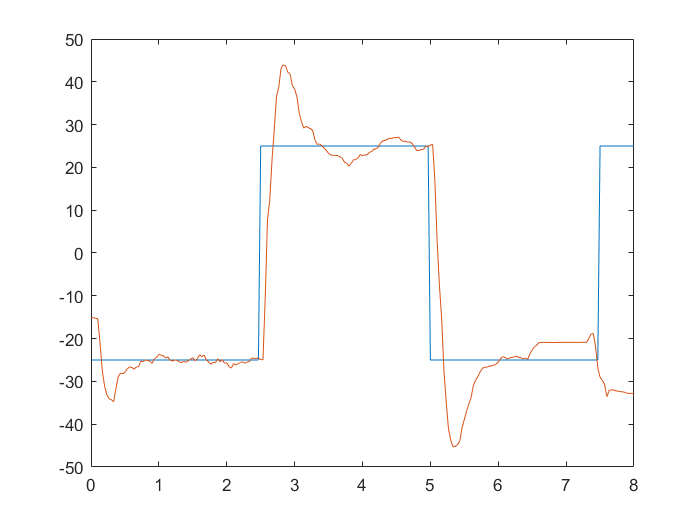

y2_25_1=scope.signals(2).values; 

y3_25_1=squeeze(y2_25_1);
y3_25_1=y3_25_1.';
constref=80;
y3_25_1=y3_25_1-constref;

plot(x1_25_1,y3_25_1);
hold off

Chosing points (step 2)

case25_1_y=y3_25_1(75:150);

Forcing first point as y=0

const25_1=y3_25_1(75);
case25_1_y=case25_1_y-const25_1;
case25_1_t=x1_25_1(1:76);

figure
plot(case25_1_t,case25_1_y);
hold on

Picking points from the reference for comparison

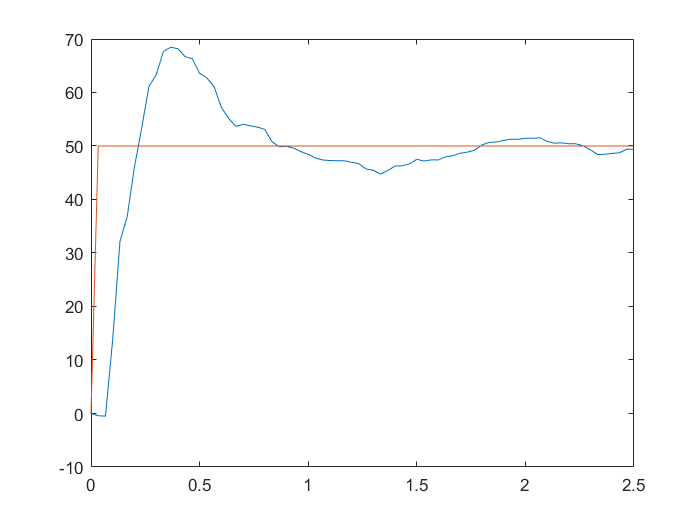

case25_1_yref=y1_25_1(75:150);
const25_1_yref=y1_25_1(75);
case25_1_yref=case25_1_yref-const25_1_yref;

plot(case25_1_t,case25_1_yref);
hold off